## Dependent sources

This example showcases how ELABorate deals with circuits containing dependent sources.

### Voltage-Controlled-Voltage-Sources

circuit = Circuit('circuits/E_src.txt');
circuit.list

ans =     'V1 1 0 DC 12
     R1 1 2 2000
     R2 2 0 4000
     R3 3 4 20000
     C1 1 2 0.0001
     C2 4 0 0.001
     E1 3 2 1 2 100
     '


ELAB.analyze(circuit)

Symbolic analysis successful (0.499921 sec).


circuit.symbolic_node_voltages

$$ans = \begin{array}{l} \left(\begin{array}{c} v_{1}=V_{1}\\ v_{2}=\frac{R_{2}\,V_{1}\,\left(C_{1}\,R_{1}\,s+C_{2}\,R_{3}\,s-C_{2}\,E_{1}\,R_{1}\,s+C_{1}\,C_{2}\,R_{1}\,R_{3}\,s^{2}+1\right)}{\sigma_{1}}\\ v_{3}=\frac{V_{1}\,\left(C_{2}\,R_{3}\,s+1\right)\,\left(R_{2}+E_{1}\,R_{1}+C_{1}\,R_{1}\,R_{2}\,s\right)}{\sigma_{1}}\\ v_{4}=\frac{V_{1}\,\left(R_{2}+E_{1}\,R_{1}+C_{1}\,R_{1}\,R_{2}\,s\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R_{1}+R_{2}+C_{1}\,R_{1}\,R_{2}\,s+C_{2}\,R_{1}\,R_{2}\,s+C_{2}\,R_{1}\,R_{3}\,s+C_{2}\,R_{2}\,R_{3}\,s-C_{2}\,E_{1}\,R_{1}\,R_{2}\,s+C_{1}\,C_{2}\,R_{1}\,R_{2}\,R_{3}\,s^{2} \end{array}$$

TF = ELAB.ec2tf(circuit,1,3)


Numerical evaluation successful (0.149412 sec).
Transfer function object created successfully (1.749869e-01 sec).

TF =
 
  s^2 + 255.1 s + 12.75
  ---------------------
  s^2 - 41.95 s + 0.375
 
Continuous-time transfer function.



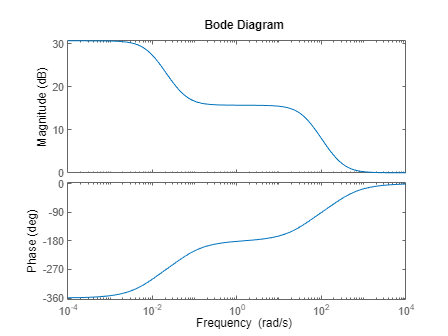

bode(TF)

### Voltage-Controlled-Current-Sources

circuit = Circuit('circuits/G_src.txt');
circuit.list

ans =     'V1 1 0 DC 12
     R1 1 2 2000
     R2 3 0 4000
     R3 4 0 8000
     C1 2 3 0.001
     G1 4 3 2 3 50
     '


ELAB.analyze(circuit)

Symbolic analysis successful (0.390834 sec).


circuit.symbolic_node_voltages

$$ans = \begin{array}{l} \left(\begin{array}{c} v_{1}=V_{1}\\ v_{2}=\frac{V_{1}\,\left(G_{1}\,R_{2}+C_{1}\,R_{2}\,s+1\right)}{\sigma_{1}}\\ v_{3}=\frac{R_{2}\,V_{1}\,\left(G_{1}+C_{1}\,s\right)}{\sigma_{1}}\\ v_{4}=-\frac{G_{1}\,R_{3}\,V_{1}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=G_{1}\,R_{2}+C_{1}\,R_{1}\,s+C_{1}\,R_{2}\,s+1 \end{array}$$

TF = ELAB.ec2tf(circuit,1,3)


Numerical evaluation successful (0.0802705 sec).
Transfer function object created successfully (1.129975e-01 sec).

TF =
 
  0.6667 s + 3.333e04
  -------------------
     s + 3.333e04
 
Continuous-time transfer function.



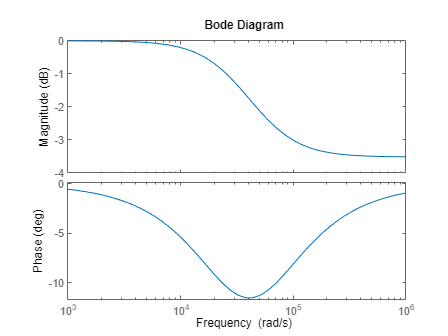

bode(TF)

### Current-Controlled-Voltage-Sources

circuit = Circuit('circuits/H_src.txt');
circuit.list

ans =     'V1 1 0 DC 12
     R1 1 2 2000
     R2 2 0 4000
     L1 3 0 0.02
     C1 3 0 0.0002
     H1 3 2 V1 10
     '


ELAB.analyze(circuit)

Symbolic analysis successful (0.407565 sec).


circuit.symbolic_node_voltages

$$ans = \begin{array}{l} \left(\begin{array}{c} v_{1}=V_{1}\\ v_{2}=\frac{R_{2}\,V_{1}\,\left(C_{1}\,H_{1}\,L_{1}\,s^{2}+L_{1}\,s+H_{1}\right)}{\sigma_{1}}\\ v_{3}=-\frac{L_{1}\,V_{1}\,s\,\left(H_{1}-R_{2}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R_{1}\,R_{2}+H_{1}\,R_{2}+L_{1}\,R_{1}\,s+L_{1}\,R_{2}\,s+C_{1}\,H_{1}\,L_{1}\,R_{2}\,s^{2}+C_{1}\,L_{1}\,R_{1}\,R_{2}\,s^{2} \end{array}$$

TF = ELAB.ec2tf(circuit,1,3)


Numerical evaluation successful (0.121159 sec).
Transfer function object created successfully (1.472788e-01 sec).

TF =
 
         2.481 s
  ----------------------
  s^2 + 3.731 s + 2.5e05
 
Continuous-time transfer function.



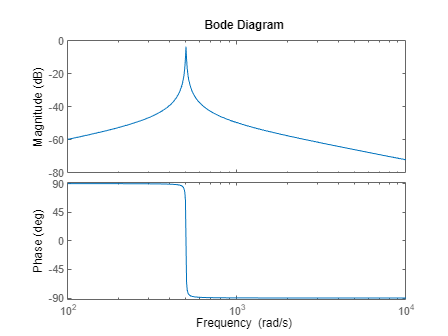

bode(TF)

### Current-Controlled-Current-Sources

circuit = Circuit('circuits/F_src.txt');
circuit.list

ans =     'V1 1 0 DC 12
     R1 1 2 2000
     R2 2 0 4000
     R3 3 0 8000
     L1 2 0 0.001
     C1 3 0 0.000001
     F1 3 2 V1 200
     '


ELAB.analyze(circuit)

Symbolic analysis successful (0.345711 sec).


circuit.symbolic_node_voltages

$$ans = \left(\begin{array}{c} v_{1}=V_{1}\\ v_{2}=-\frac{L_{1}\,R_{2}\,V_{1}\,s\,\left(F_{1}-1\right)}{R_{1}\,R_{2}+L_{1}\,R_{1}\,s+L_{1}\,R_{2}\,s-F_{1}\,L_{1}\,R_{2}\,s}\\ v_{3}=\frac{F_{1}\,R_{3}\,V_{1}\,\left(R_{2}+L_{1}\,s\right)}{\left(C_{1}\,R_{3}\,s+1\right)\,\left(R_{1}\,R_{2}+L_{1}\,R_{1}\,s+L_{1}\,R_{2}\,s-F_{1}\,L_{1}\,R_{2}\,s\right)} \end{array}\right)$$

TF = ELAB.ec2tf(circuit,1,3)


Numerical evaluation successful (0.0966423 sec).
Transfer function object created successfully (1.222537e-01 sec).

TF =
 
    -251.9 s - 1.008e09
  -----------------------
  s^2 - 9951 s - 1.259e06
 
Continuous-time transfer function.



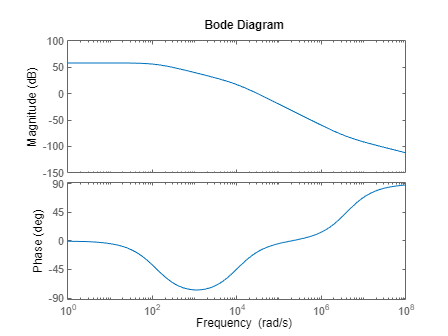

bode(TF)